# Train Network for Green Adjustments

Load saved data

load trainHueVariance.mat
paths = T.path

paths = 1997×1 cell array
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.12.08.12.50.29_171a4088-85f1-4fa9-8ffa-211d9dd58f65_IMG_20181208_104716_1545334821.tif'         }
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\4168.tif'                                                                                            }
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\5655.tif'                                                                                            }
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.06.15.20.38.45_03399e51-a913-4ce7-8b00-f2f74804b1d2_IMG_20180615_145628_358377385.tif'          }
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.06.20.18.34.23_608c74c6-8fa7-4d93-b734-98e6f102adc6_IMG_20180620_171225_-250609795.tif'         }
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.12.09.11.42.25_7bba5cd3-c663-4123-9c88-df6f568601f0_IMG_20181208_110642_-951584394.tif'         }
    {'C:\Users\User\

Setup Transfer Learning

net = alexnet

net =   SeriesNetwork with properties:

    Layers: [25×1 nnet.cnn.layer.Layer]


layers = net.Layers

layers =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    

Replace the last two layers

layers(end-2:end) = [];
newLayers = [fullyConnectedLayer(1,'Name','fc8');...
    regressionLayer('Name','regressionoutput')]

newLayers =   2x1 Layer array with layers:

     1   'fc8'                Fully Connected     1 fully connected layer
     2   'regressionoutput'   Regression Output   mean-squared-error


layers =[layers; newLayers]

layers =   24x1 Layer array with layers:

     1   'data'               Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'              Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'              ReLU                          ReLU
     4   'norm1'              Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'              Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'              Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'              ReLU                          ReLU
     8   'norm2'              Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'              Max 

Check Network validity

analyzeNetwork(layers)

Choose data for validation

validx = randperm(height(T), round(height(T) * 0.25))

validx =          728         385         241        1300         622         140        1295        1690         202         681         421         182         502         411        1222        1768        1420        1714        1659          39         655         112        1329         470         938         109        1657        1182         551        1900         173          93        1214        1903         248         729         537         254         757         614        1673        1552        1220        1079         462         464         597         437         314        1735



validationData = T(validx,:)

validationData = 499×2 table
                                                                              path                                                                              aAdjustment
    ________________________________________________________________________________________________________________________________________________________    ___________

    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.12.08.13.11.37_75082c1a-1818-429c-a7e9-566d17a2116f_IMG_20181208_110240_-80376529.tif'                -1.8912  
    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.07.02.15.15.01_c92c21e1-896d-4b78-8829-2cbf47eed5bf_IMG_20180702_132757_1299273968.tif'               -10.302  
    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.06.20.18.28.32_fc3f7641-19e3-42f6-a631-4a5f92dd3719_IMG_20180620_164209_-196284477.tif'               -1.5753  
    'C:\Users\User\Google Drive\Greenstand

T(validx,:) = []

T = 1498×2 table
                                                                              path                                                                              aAdjustment
    ________________________________________________________________________________________________________________________________________________________    ___________

    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.12.08.12.50.29_171a4088-85f1-4fa9-8ffa-211d9dd58f65_IMG_20181208_104716_1545334821.tif'                2.2082  
    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\4168.tif'                                                                                                  -9.7606  
    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\5655.tif'                                                                                                  -9.4305  
    'C:\Users\User\Google Drive\Greenstand\HueAdjusted

Set training options

opts = trainingOptions('adam', 'MaxEpochs',14,...
    'Plots','training-progress',...
'ValidationData',validationData,'ExecutionEnvironment','gpu')

opts =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 1.0000e-03
     LearnRateScheduleSettings: [1×1 struct]
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 14
                 MiniBatchSize: 128
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: [499×2 table]
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'gpu'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 'training-progress'
                SequenceLength: 'longest'
      

Perform Training

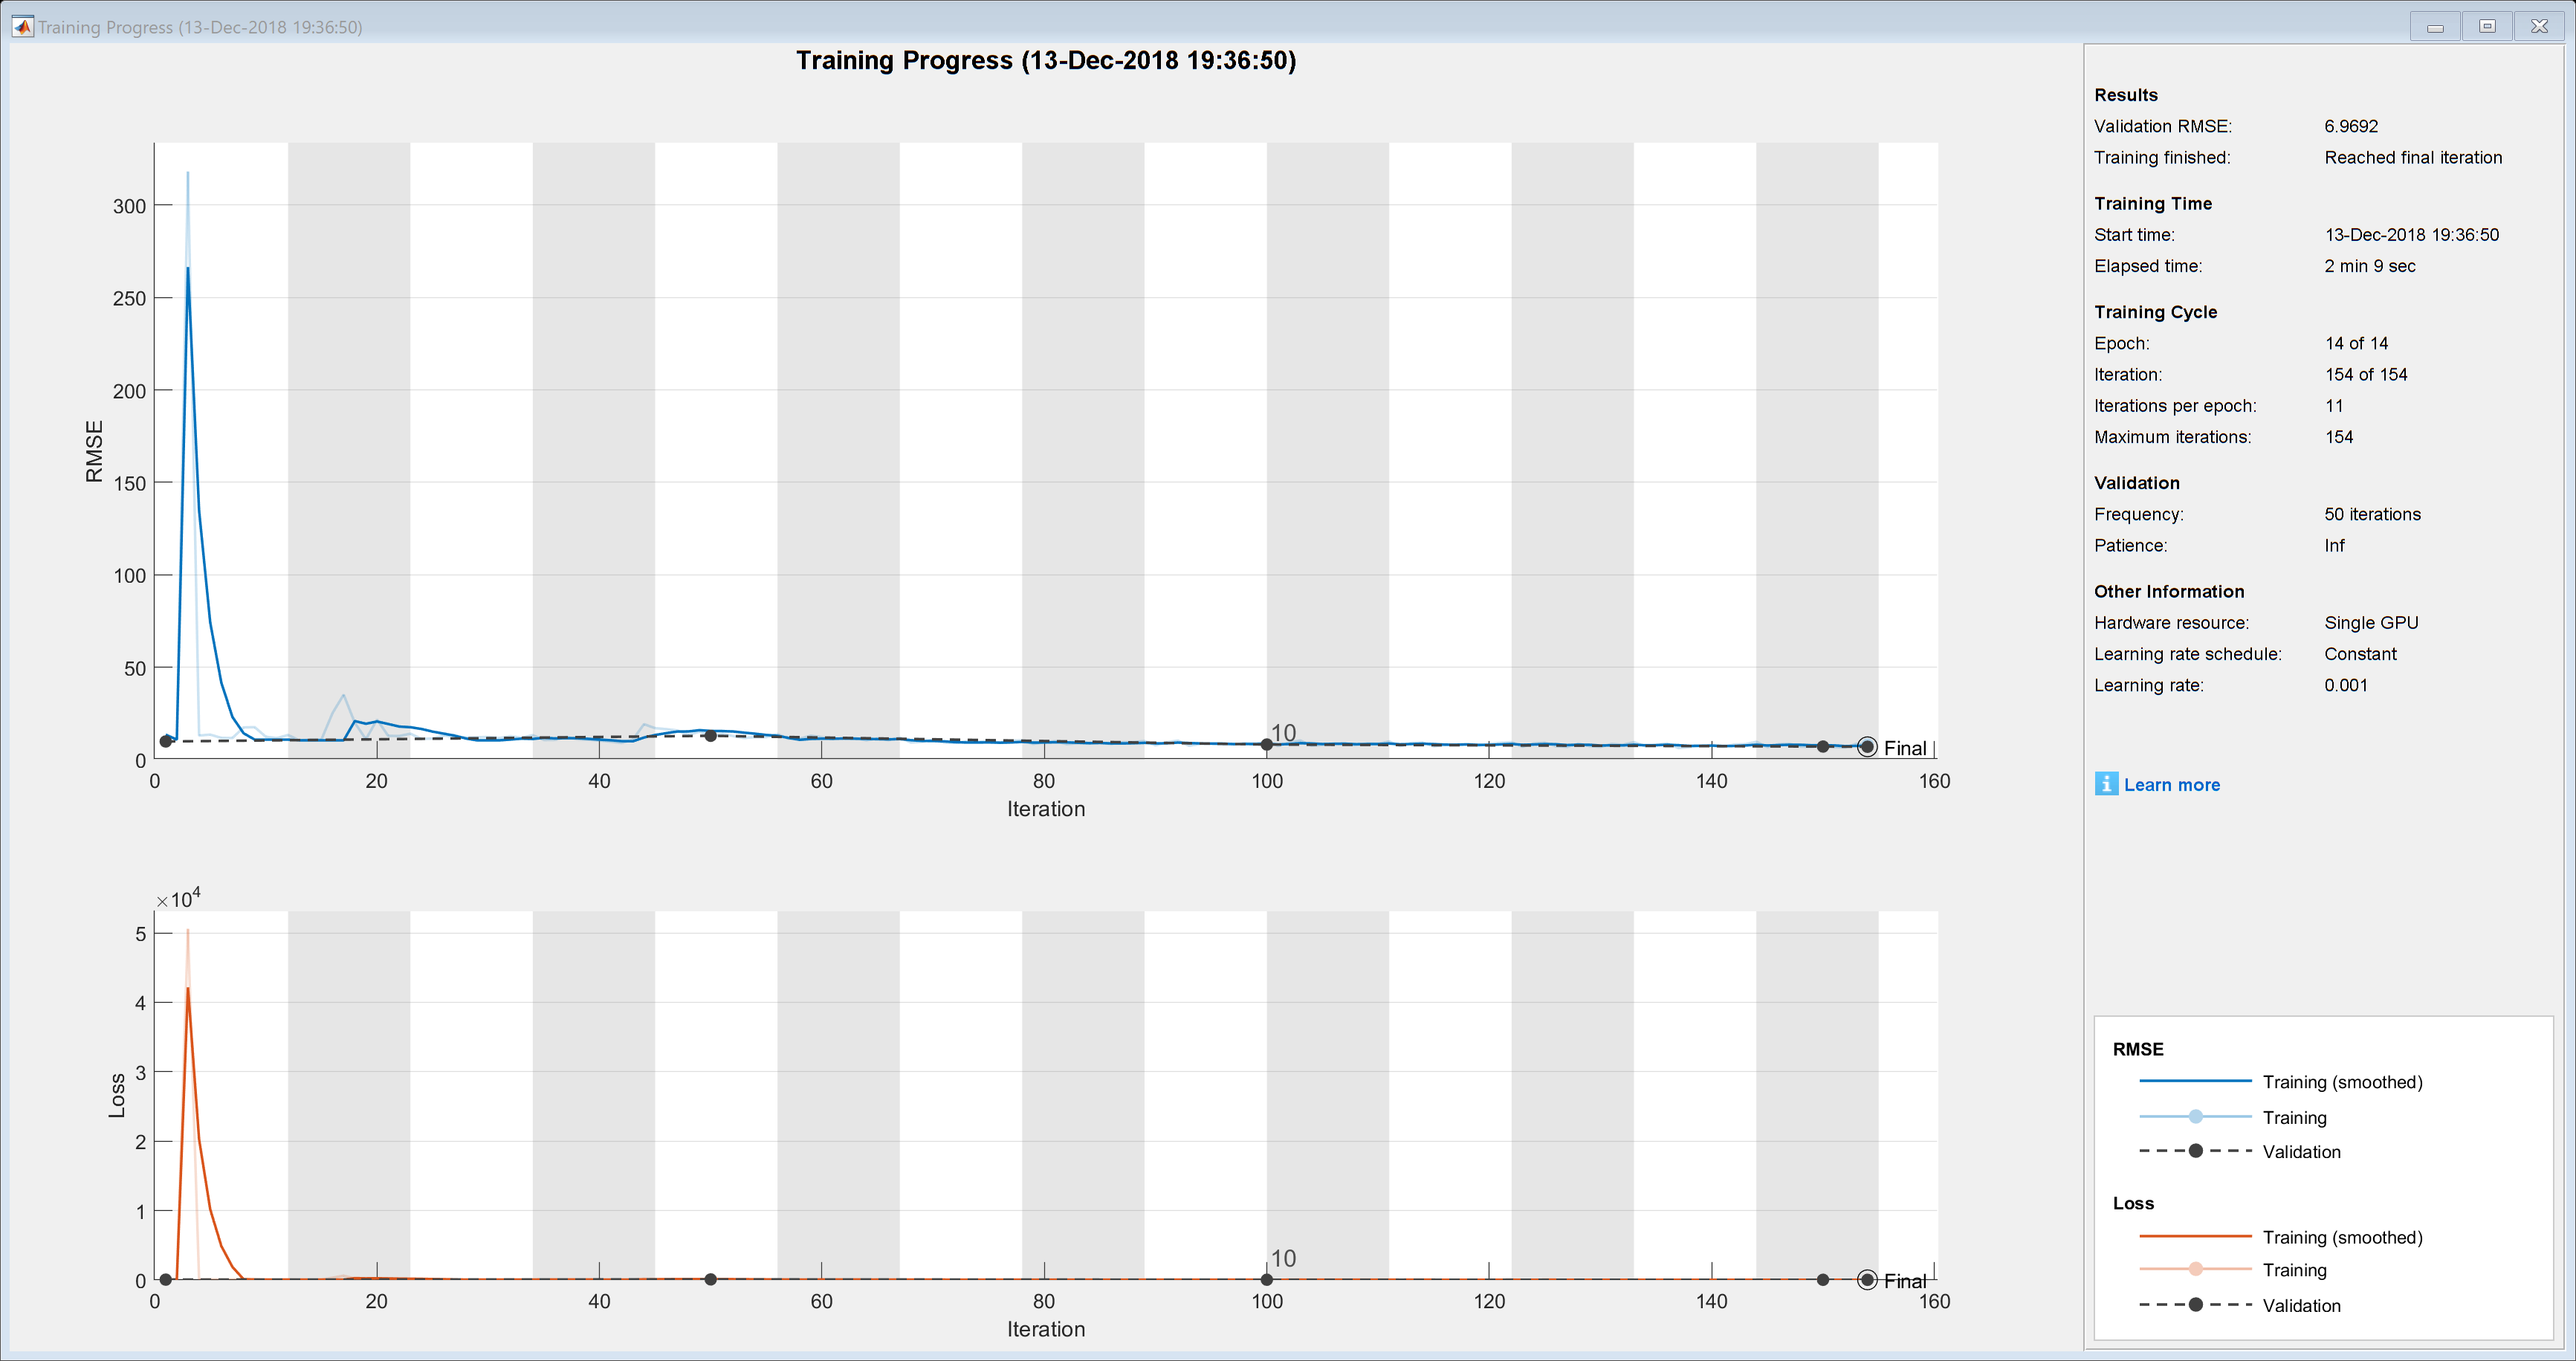

Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |        13.52 |         9.83 |      91.4518 |      48.2873 |          0.0010 |
|       5 |          50 |       00:00:45 |        12.26 |        12.90 |      75.0936 |      83.2550 |          0.0010 |
|      10 |         100 |       00:01:25 |         9.60 |         8.18 |      46.0986 |      33.4909 |          0.0010 |
|      14 |         150 |       00:02:04 |         7.53 |         7.10 |      28.3404 |      25.1791 |          0.0010 

hueCorrectionNetwork =   SeriesNetwork with properties:

    Layers: [24×1 nnet.cnn.layer.Layer]


hueCorrectionNetwork = trainNetwork(T, layers, opts)

Test an image

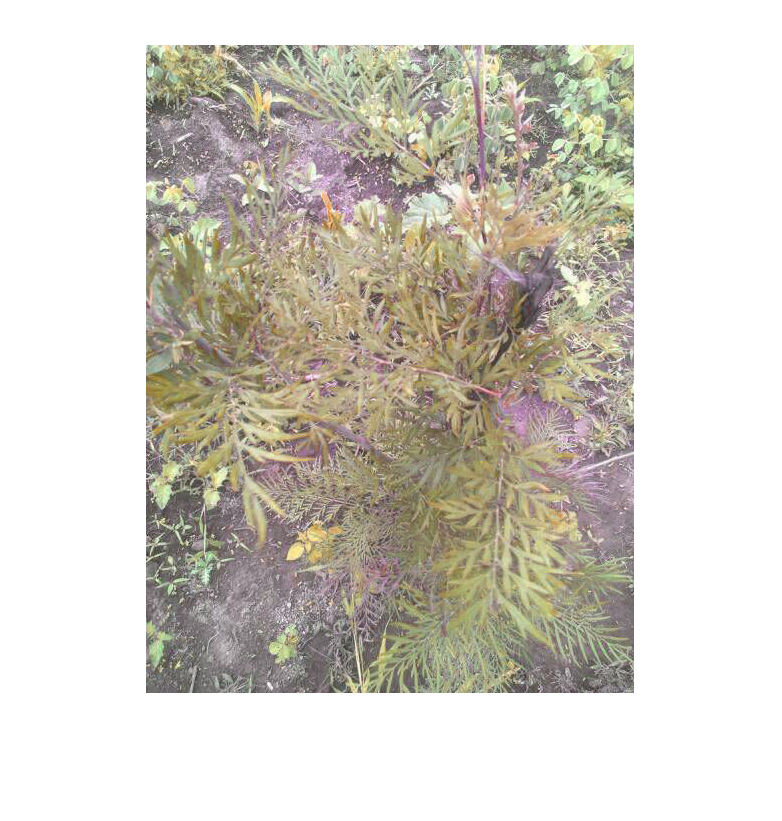

test = imread('226.tif');
imshow(test);

resizedTest = imresize(test, [227 227]);

correction = predict(hueCorrectionNetwork, resizedTest)

correction = single
-6.8367

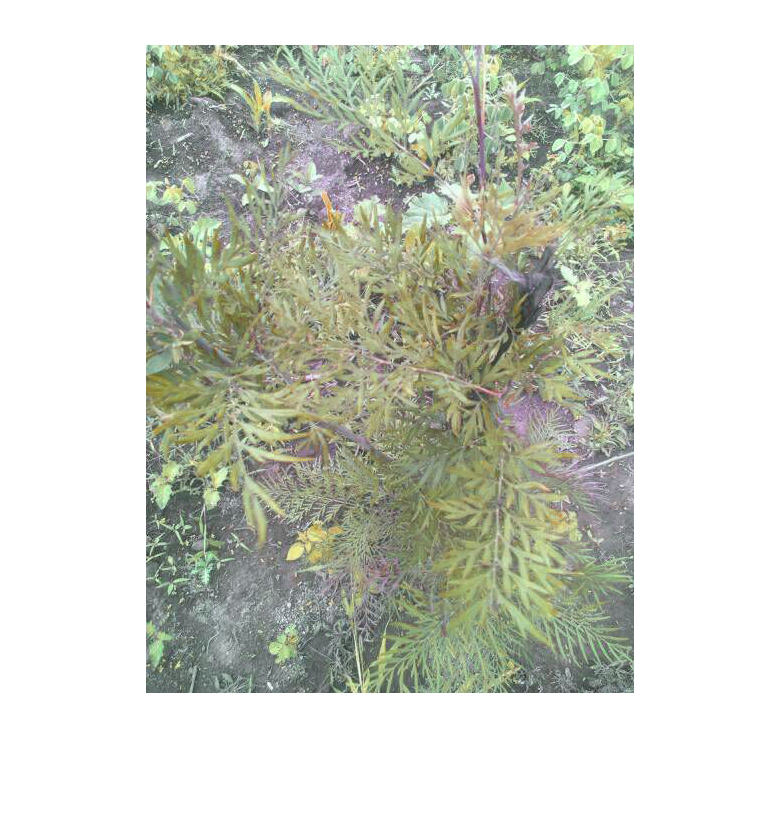

 
 labTest = rgb2lab(test);
 labTest(:,:,2) =  labTest(:,:,2) + correction;


 rgbImage = lab2rgb(labTest);
 imshow(rgbImage);

 imwrite(rgbImage,'226Corrected.tif','tif');
 
 
 

 

Save the network

 save('hueCorrectionNetwork.mat','hueCorrectionNetwork');